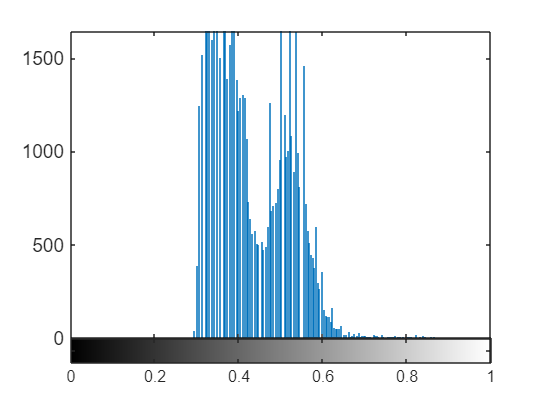

img=imread('pout.tif');
img=im2double(img);
figure;imhist(img);

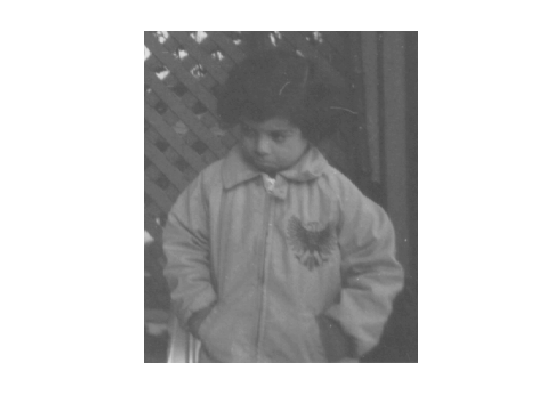

imshow(img);

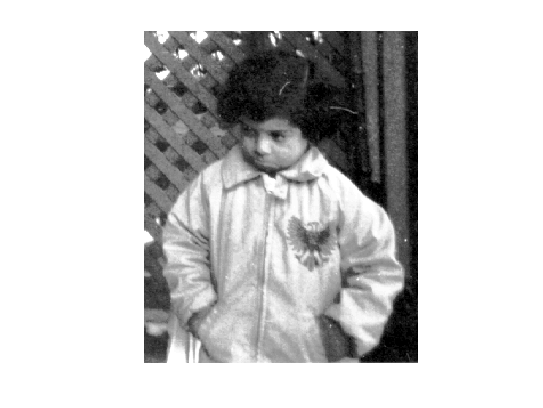

img2=histeq(img);
imshow(img2);

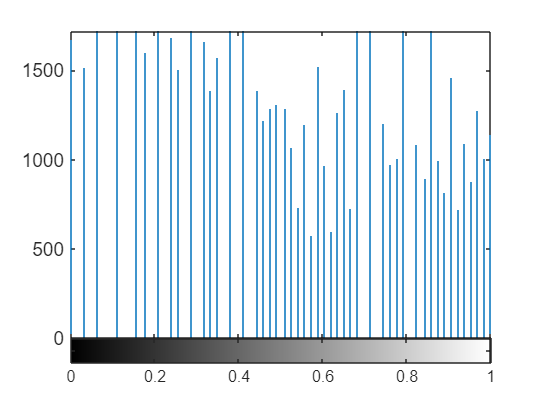

figure;imhist(img2);

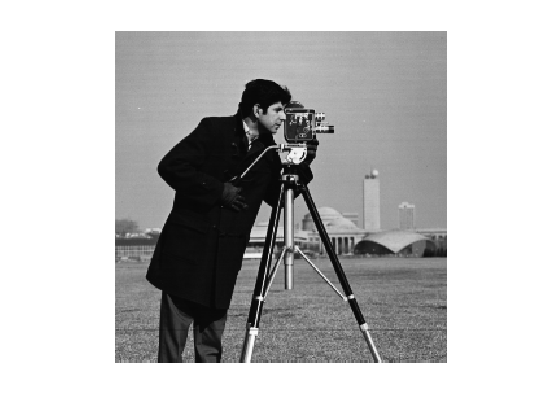



image=imread("peppers.png");
image=im2double(image);
labimage=rgb2lab(image);
L=labimage(:,:,1);
L_scale=L/100;
L_adj=imadjust(L_scale);
L_eq=histeq(L_scale);
L_adapt=adapthisteq(L_scale);
L_adj=L_adj*100;
L_eq=L_eq*100;
L_adapt=L_adapt*100;

lab_adj=labimage;
lab_adj(:,:,1)=L_adj;
lab_eq=labimage;
lab_eq(:,:,1)=L_eq;
lab_adapt=labimage;
lab_adapt(:,:,1)=L_adapt;


rgbadj=lab2rgb(lab_adj);
rgbeq=lab2rgb(lab_eq);
rgbadapt=lab2rgb(lab_adapt);





image2=imread("cameraman.png");
magnifyfac=5.5;
J=imresize(image2,magnifyfac);
imshow(image2);

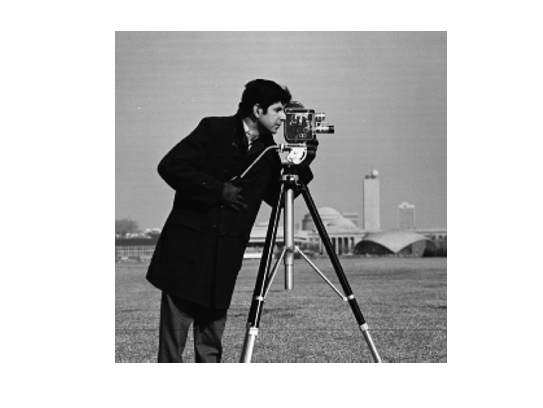

imshow(J);